# Example 1: executing a simulation

### This assumes the database and default data has been loaded 

## 1. Connect to the database and select a UAV

% load the workspace necessities, must be in root directory
addpath(genpath(pwd));

% the database connection
conn = db_connect('nasadb');

% check out what UAVs are in the db
uav_tb = select(conn, 'select asset_tb.serial_number, uav_tb.* from uav_tb join asset_tb on asset_tb.id = uav_tb.id;')

uav_tb = 1×13 table
    serial_number    id    airframe_id    battery_id    m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    max_flight_time
    _____________    __    ___________    __________    _____    _____    _____    _____    _____    _____    _____    _____    _______________

     {'35E24B'}      11         1             2          10        9        8        7        6        5        4        3            18       


% load the UAV 
uav = load_uav(conn, uav_tb.serial_number{1})

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 18
                 id: 11
     dynamics_srate: 0.0250
               mass: 1.8000


% close the connection and clear the table
conn.close();
clear('uav_tb', 'conn');

## 2. Setup the simulation parameters

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 2400;

% performance thresholds
sim_params.perf_param_thresh.max_pos_err  = 6.5;
sim_params.perf_param_thresh.avg_pos_err  = 1.9;
sim_params.perf_param_thresh.min_soc      = .3;
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.2;
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6;

% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/IC_HoverAt10ftOcto.mat').IC;
sim_params.battery_estimator   = load('estimation/batteryestimator').BatteryEstimator;
sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;

% wind (really need a better implementation of wind)
processes.environment.wind.gust = [1.2, .5];

## 3. Load the trajectory

% load the trajectory information
% there are 37 different trajectories, this function will return one that
% is closest to the second parameter in the function (uav.max_flight_time)
% with valid numbers (minutes) between 6 and 22. 
%trajectory = get_trajectory('trajectories/trajectories.csv', uav.max_flight_time);
trajectory = get_trajectory('trajectories/trajectories.csv', 8);

% update initial conditions
sim_params.initial_conditions.X = trajectory.x_ref_points(1,2);
sim_params.initial_conditions.Y = trajectory.y_ref_points(1,2);
sim_params.initial_conditions.state(1) = trajectory.x_ref_points(1,2);
sim_params.initial_conditions.state(2) = trajectory.y_ref_points(1,2);

% set the desired velocity
trajectory.velocity = 1.3; % m/s

## 4. Simulate

tic
sim('simulink/uav_simulation.slx');
toc

Elapsed time is 205.161139 seconds.


## 5. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

ans = 1

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;
1/mean(diff(t_dynamics))

ans = 40

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;

ans = 40.4963

1/mean(diff(t_sim))

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


ans = 467

#### The safest bet is to always use the time vector that comes with the variable data itself. In the end, these will be synchronized to a time table sampled at 4hz and then inserted into the database.

### Battery data

All battery data is sampled at 1hz. This data will be converted to a time table, interpolated and upsampled at 4hz. 

- v (voltage)

- z (state of charge)

- i (current draw)

- r (internal resistance)

% the time vector

ans =     4.1732
    4.1672
    4.1654
    4.1635
    4.1625
    4.1630
    4.1605
    4.1589
    4.1583
    4.1582


battery.battery_true.v.Time'
battery.battery_true.v.Time(end)
% the data vector
battery.battery_true.v.Data
% battery.battery_true.i.Data
% battery.battery_true.z.Data
%battery.battery_true.r.Data

#### Check if there is estimation data for the battery

- estimates for v, z, and r

- variance for r and z

- TODO get variance for v

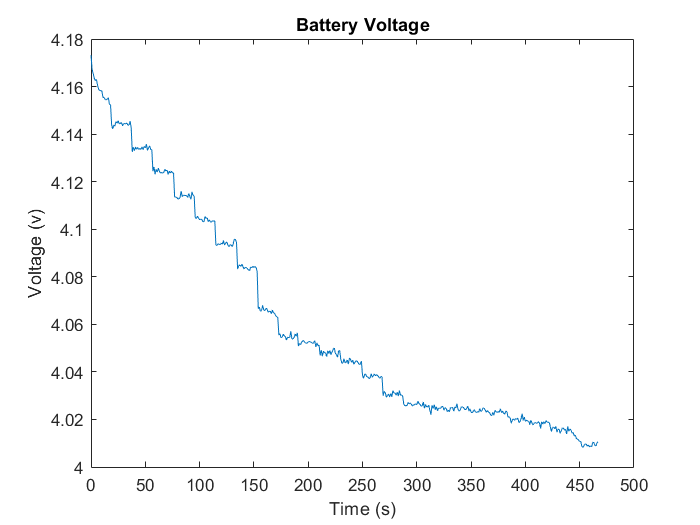

x =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


if isfield(battery, 'battery_hat')
    % battery.battery_hat.v.Data
    % battery.battery_hat.z.Data
    % battery.battery_hat.r.Data
    % battery.battery_hat.r_var.Data
    % battery.battery_hat.z_var.Data
end

#### Prepare the battery data

f1 = figure(1); clf;
plot(battery.battery_true.v.Time, battery.battery_true.v.Data);

ans = 468

xlabel("Time (s)");

ans = 467

ylabel("Voltage (v)");

ans = 467.5000

title("Battery Voltage");

x =          0    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000    1.7500    2.0000    2.2500    2.5000    2.7500    3.0000    3.2500    3.5000    3.7500    4.0000    4.2500    4.5000    4.7500    5.0000    5.2500    5.5000    5.7500    6.0000    6.2500    6.5000    6.7500    7.0000    7.2500    7.5000    7.7500    8.0000    8.2500    8.5000    8.7500    9.0000    9.2500    9.5000    9.7500   10.0000   10.2500   10.5000   10.7500   11.0000   11.2500   11.5000   11.7500   12.0000   12.2500


x = 0:.25:length(battery.battery_true.v.Time)

ans = 467.5000

#### Back to the subject of different sample rates, there are also different end-times. in this case, we want to preserve the additional .5 found in time.Time(end) vs the the time found in battery.battery_true.v.Time(end). This is because the battery is sampled at whole seconds, so the simulation carried on for an additional .5 seconds. x, the new time vector for the battery data, will then need the last two values dropped. See below for the end times and length of time and data vectors.

x(end)
battery.battery_true.v.Time(end)

y =     4.1732    4.1705    4.1686    4.1675    4.1672    4.1657    4.1649    4.1649    4.1654    4.1642    4.1633    4.1631    4.1635    4.1622    4.1615    4.1617    4.1625    4.1619    4.1617    4.1622    4.1630    4.1618    4.1608    4.1604    4.1605    4.1591    4.1583    4.1583    4.1589    4.1578    4.1574    4.1576    4.1583    4.1574    4.1570    4.1573    4.1582    4.1575    4.1573    4.1576    4.1582    4.1567    4.1556    4.1552    4.1554    4.1544    4.1540    4.1545    4.1555    4.1545


time.Time(end)

y =     4.1732    4.1705    4.1686    4.1675    4.1672    4.1657    4.1649    4.1649    4.1654    4.1642    4.1633    4.1631    4.1635    4.1622    4.1615    4.1617    4.1625    4.1619    4.1617    4.1622    4.1630    4.1618    4.1608    4.1604    4.1605    4.1591    4.1583    4.1583    4.1589    4.1578    4.1574    4.1576    4.1583    4.1574    4.1570    4.1573    4.1582    4.1575    4.1573    4.1576    4.1582    4.1567    4.1556    4.1552    4.1554    4.1544    4.1540    4.1545    4.1555    4.1545


x = x(1:end-2)

#### Now x (for the battery data) has the correct end time. 

x(end)

#### y has an extra entry, which is ok, we will drop it as well

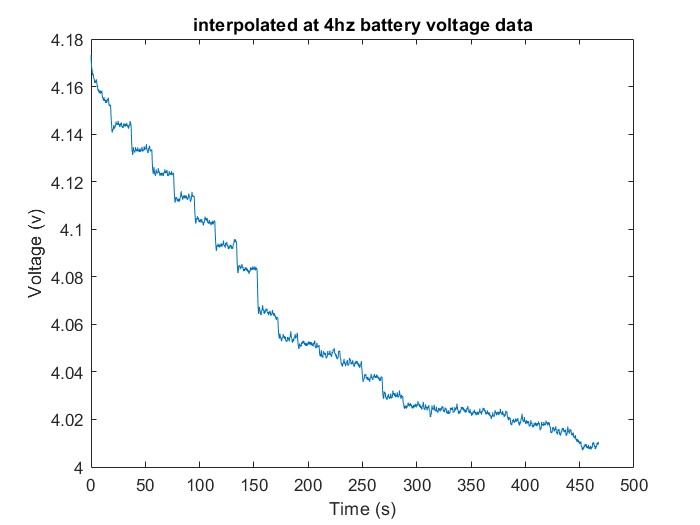

y = interp(battery.battery_true.v.Data, 4)'
y = y(1:end-1)

#### Now replot the data and verify its integrity

f2 = figure(2); clf;
plot(x, y);
xlabel("Time (s)");

ans =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500    0.7750    0.8000    0.8250    0.8500    0.8750    0.9000    0.9250    0.9500    0.9750    1.0000    1.0250    1.0500    1.0750    1.1000    1.1250    1.1500    1.1750    1.2000    1.2250


ylabel("Voltage (v)");

ans = 467.5000

title("interpolated at 4hz battery voltage data");

### Control and position data

Notice the different sample rates. 

errors.ctrl_err.x_error.Time'
errors.ctrl_err.x_error.Time(end)



